# Métodos Numéricos y Programación

*F. Pena*

## Tema 2. Gráficas, archivos de datos y clases

### Simbólico y numérico

Para realizar cálculo simbólico, es necesario la *toolbox* `symbolic`.

syms x
f = sin(x/2)

$$f = \sin\left(\frac{x}{2}\right)$$

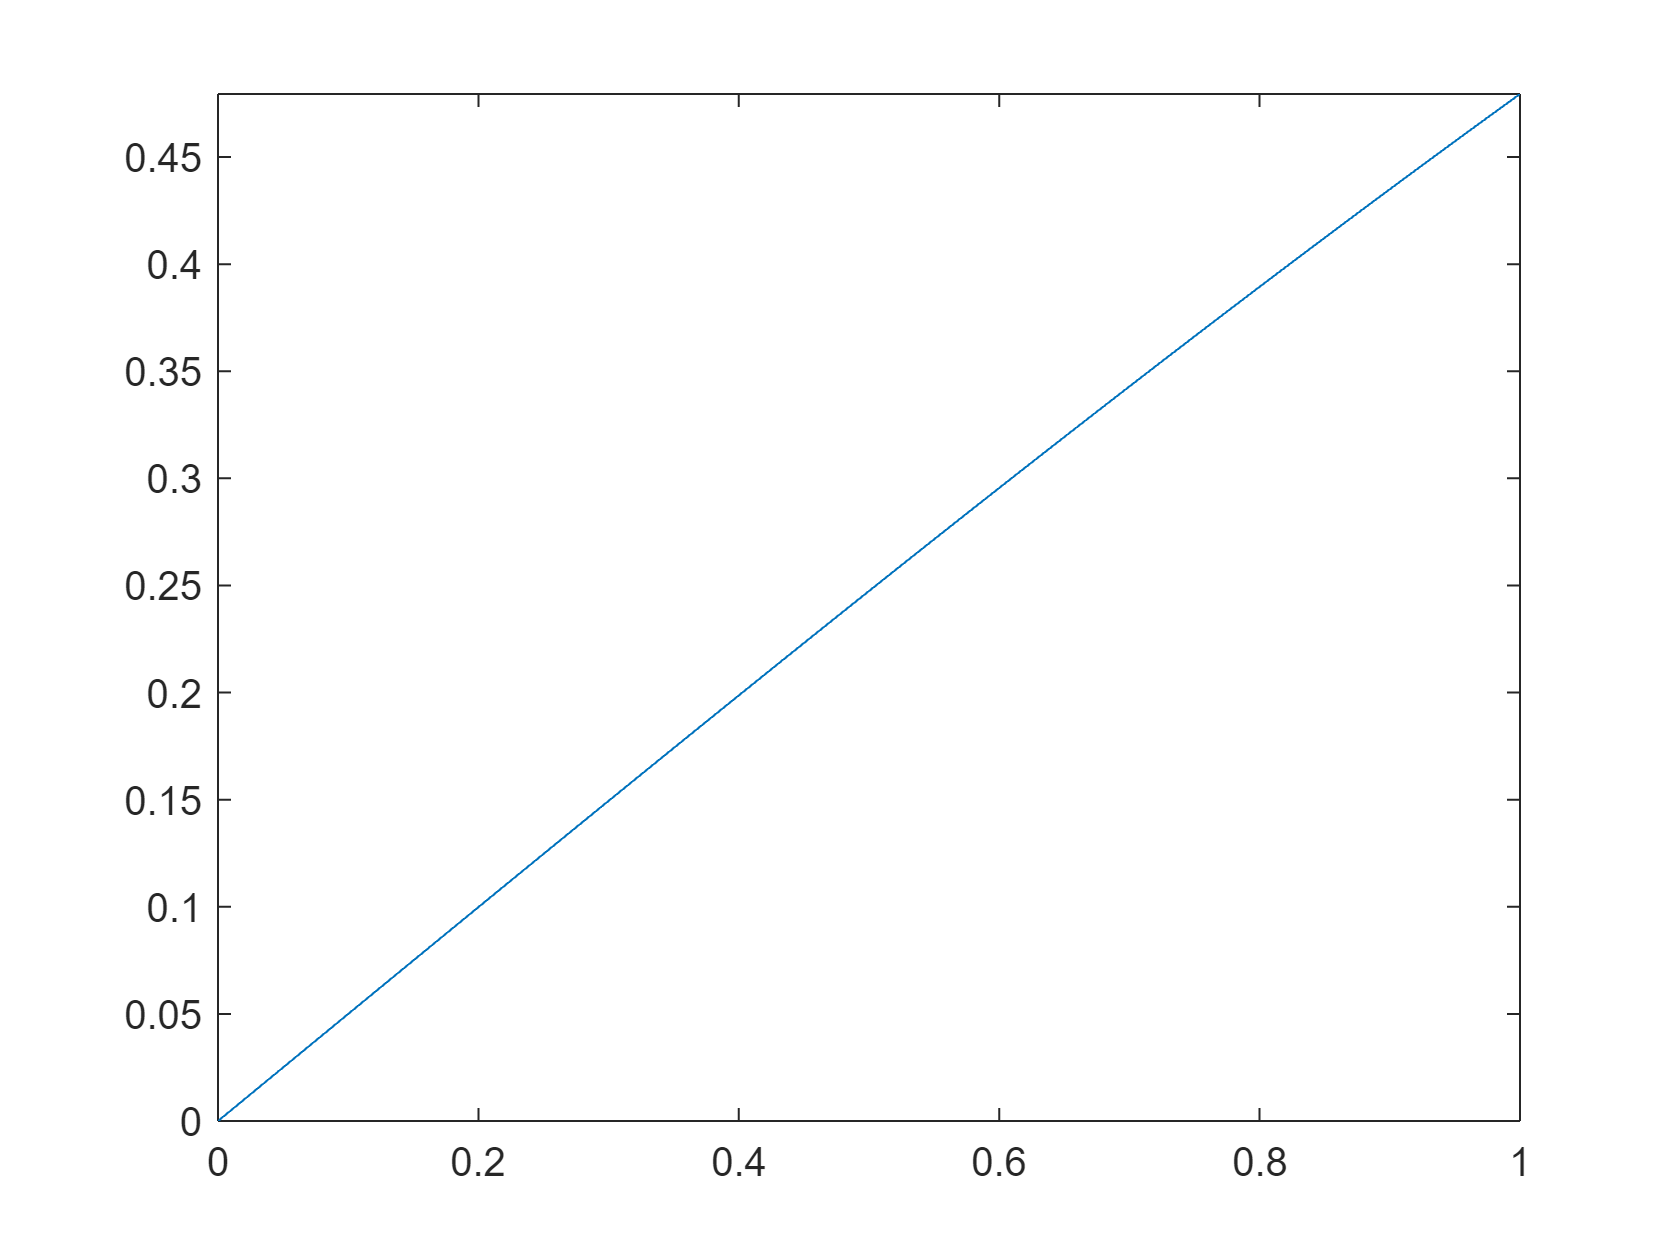

fplot(f, [0 1])

subs(f, x, pi/2)

$$ans = \frac{\sqrt{2}}{2}$$

x = sym(pi/2) %ojo, x = pi/2 devolvería x = 1.5708

$$x = \frac{\pi }{2}$$

vpa(x,16) %aún simbólico

$$ans = 1.570796326794897$$

double(x) %numérico

ans = 1.5708

g = matlabFunction(f)

g = function_handle with value:
    @(x)sin(x./2.0)


#### **Cálculo de raíces de ecuaciones no lineales**

- [`solve`](https://es.mathworks.com/help/symbolic/sym.solve.html): resuelve ecuaciones no lineales simbólicamente.

syms x
eqn = x^3 - 4*x + 2 == 0;
sol = solve(eqn, x, Real=true)

$$sol = \left(\begin{array}{c} \mathrm{root}\left(z^{3}-4\,z+2,z,1\right)\\ \mathrm{root}\left(z^{3}-4\,z+2,z,2\right)\\ \mathrm{root}\left(z^{3}-4\,z+2,z,3\right) \end{array}\right)$$

vpa(sol)

$$ans = \left(\begin{array}{c} 0.53918887281088911652587590269852\\ 1.6751308705666460708896217981501\\ -2.2143197433775351874154977008486 \end{array}\right)$$

double(sol)

ans =     0.5392
    1.6751
   -2.2143


- [`fzero`](https://es.mathworks.com/help/matlab/ref/fzero.html): encuentra la raíz aproximada de una función no lineal en un punto cercano al iterante inicial.

f = @(x) x^3 - 4*x + 2;
raiz = fzero(f, 0)

raiz = 0.5392

f(raiz)

ans = 0

#### **Cálculo de raíces de sistemas no lineales**

- [`solve`](https://es.mathworks.com/help/symbolic/sym.solve.html): resuelve sistemas no lineales simbólicamente.

syms x y
eqns = [2*x + y == 3, x - y == 1];
sol = solve(eqns, [x, y])

sol = struct with fields:
    x: 4/3
    y: 1/3


[sol.x sol.y]

$$ans = \left(\begin{array}{cc} \frac{4}{3} & \frac{1}{3} \end{array}\right)$$

- [`fsolve`](https://es.mathworks.com/help/matlab/ref/fsolve.html): resuelve sistemas de ecuaciones no lineales numéricamente.

F = @(x) [x(1)^2 + x(2)^2 - 1; x(1)^2 - x(2)];
x0 = [0.5, 0.5];
sol = fsolve(F, x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


sol =     0.7862    0.6180


F(sol)

ans = 1.0e-09 *

    0.1675
    0.1676


#### **Sistemas lineales de ecuaciones**

- [`linsolve`](https://es.mathworks.com/help/matlab/ref/linsolve.html): resuelve sistemas lineales simbólicos de la forma $Ax=b$.

A = [ 2 1  1;
     -1 1 -1;
      1 2  3];
B = [2; 3; -10];
X = linsolve(A,B)

X =      3
     1
    -5


- `A\b`: resuelve un sistema lineal $Ax=b$.

A = [2 1; 1 -1];
b = [3; 1];
sol = A\b

sol =     1.3333
    0.3333


#### Optimización de una variable

- [`fminbnd`](https://es.mathworks.com/help/matlab/ref/fminbnd.html): encuentra el mínimo de una función de una variable en el intervalo $[a,b]$ (numérico).

f = @(x) x^2 + 2*x + 1;
fmin = fminbnd(f, -10, 10)

fmin = -1.0000

#### **Optimización de varias variables**

- [`fminunc`](https://es.mathworks.com/help/optim/ug/fminunc.html): minimiza una función multivariable sin restricciones, usando un valor inicial (numérico).

f = @(x) x(1).^2 + x(2).^2 + 3*x(1).*x(2);
fmin = fminunc(f, [0, 0])


Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>


fmin =      0     0


#### **Derivación**

- [`diff`](https://es.mathworks.com/help/symbolic/sym.diff.html): deriva una función con respecto a una variable.

syms x
f = x^3 + 2*x^2 + x;
df = diff(f, x)

$$df = 3\,x^{2}+4\,x+1$$

- [`diff`](https://es.mathworks.com/help/matlab/ref/diff.html): calcula la derivada numérica aproximada de un conjunto de puntos.

x = 0:0.1:10;
y = sin(x);
dy_dx = diff(y)./diff(x)

dy_dx =     0.9983    0.9884    0.9685    0.9390    0.9001    0.8522    0.7958    0.7314    0.6597    0.5814    0.4974    0.4083    0.3152    0.2189    0.1205    0.0208   -0.0791   -0.1782   -0.2755   -0.3700   -0.4609   -0.5471   -0.6279   -0.7024   -0.7699   -0.8297   -0.8812   -0.9239   -0.9574   -0.9813   -0.9954   -0.9995   -0.9937   -0.9780   -0.9524   -0.9174   -0.8732   -0.8202   -0.7591   -0.6904   -0.6147   -0.5330   -0.4459   -0.3544   -0.2593   -0.1616   -0.0623    0.0376    0.1371    0.2353


- [`gradient`](https://es.mathworks.com/help/matlab/ref/gradient.html): calcula el gradiente numérico de una función.

x = 0:0.1:10;
y = sin(x);
dy_dx = gradient(y, x)

dy_dx =     0.9983    0.9933    0.9784    0.9537    0.9195    0.8761    0.8240    0.7636    0.6955    0.6206    0.5394    0.4528    0.3618    0.2671    0.1697    0.0706   -0.0292   -0.1286   -0.2268   -0.3228   -0.4155   -0.5040   -0.5875   -0.6652   -0.7362   -0.7998   -0.8555   -0.9026   -0.9407   -0.9693   -0.9883   -0.9975   -0.9966   -0.9858   -0.9652   -0.9349   -0.8953   -0.8467   -0.7897   -0.7247   -0.6526   -0.5739   -0.4894   -0.4001   -0.3068   -0.2104   -0.1120   -0.0124    0.0874    0.1862


#### **Integración**

- [`int`](https://es.mathworks.com/help/symbolic/sym.int.html): integra una función con respecto a una variable de manera indefinida.

syms x
f = x^2 + 3*x + 2;
int(f, x)

$$ans = \frac{x\,\left(2\,x^{2}+9\,x+12\right)}{6}$$

- [`integral`](https://es.mathworks.com/help/matlab/ref/integral.html?s_tid=doc_ta): Integra numéricamente una función en el intervalo $[a,b]$.

f = @(x) x.^2 + 3*x + 2;
integral_def = integral(f, 0, 1)

integral_def = 3.8333

- [integral2](https://es.mathworks.com/help/matlab/ref/integral2.html?s_tid=doc_ta): integración numérica de integrales dobles.

fun = @(x,y) 1./( sqrt(x + y) .* (1 + x + y).^2 );
ymax = @(x) 1 - x;
q = integral2(fun,0,1,0,ymax)

q = 0.2854

#### **Interpolación**

- `interp1`: interpolación numérica en puntos $x_i$ (numérico).

x = [1 2 3 4];
y = [1 4 9 16];
xi = 2.5;
yi = interp1(x, y, xi)

yi = 6.5000

- `spline`: interpolación cúbica por splines.

yi = spline(x, y, xi)

yi = 6.2500

- [`interp2`](https://es.mathworks.com/help/matlab/ref/interp2.html): Interpolación de datos 2D

#### **Cálculo de autovalores y autovectores**

- [`eig`](https://es.mathworks.com/help/symbolic/sym.eig.html): calcula los autovalores de una matriz simbólica.

syms a b c d
A = [a b; c d]; 
autovalores = eig(A)

$$autovalores = \left(\begin{array}{c} \frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\\ \frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} \end{array}\right)$$

[V, D] = eig(A)

$$V = \left(\begin{array}{cc} \frac{\frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}}{c}-\frac{d}{c} & \frac{\frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}}{c}-\frac{d}{c}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} \frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} & 0\\ 0 & \frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} \end{array}\right)$$

- [`eig`](https://es.mathworks.com/help/matlab/ref/eig.html): calcula los autovalores y autovectores de una matriz numérica.

A = [2 1; 1 3];
[V, D] = eig(A)

V =    -0.8507    0.5257
    0.5257    0.8507


D =     1.3820         0
         0    3.6180


eigs(A, 1) %calcula los k autovalores más grandes

ans = 3.6180

### Gráficas

#### **Gráfica de una función numérica de una variable**

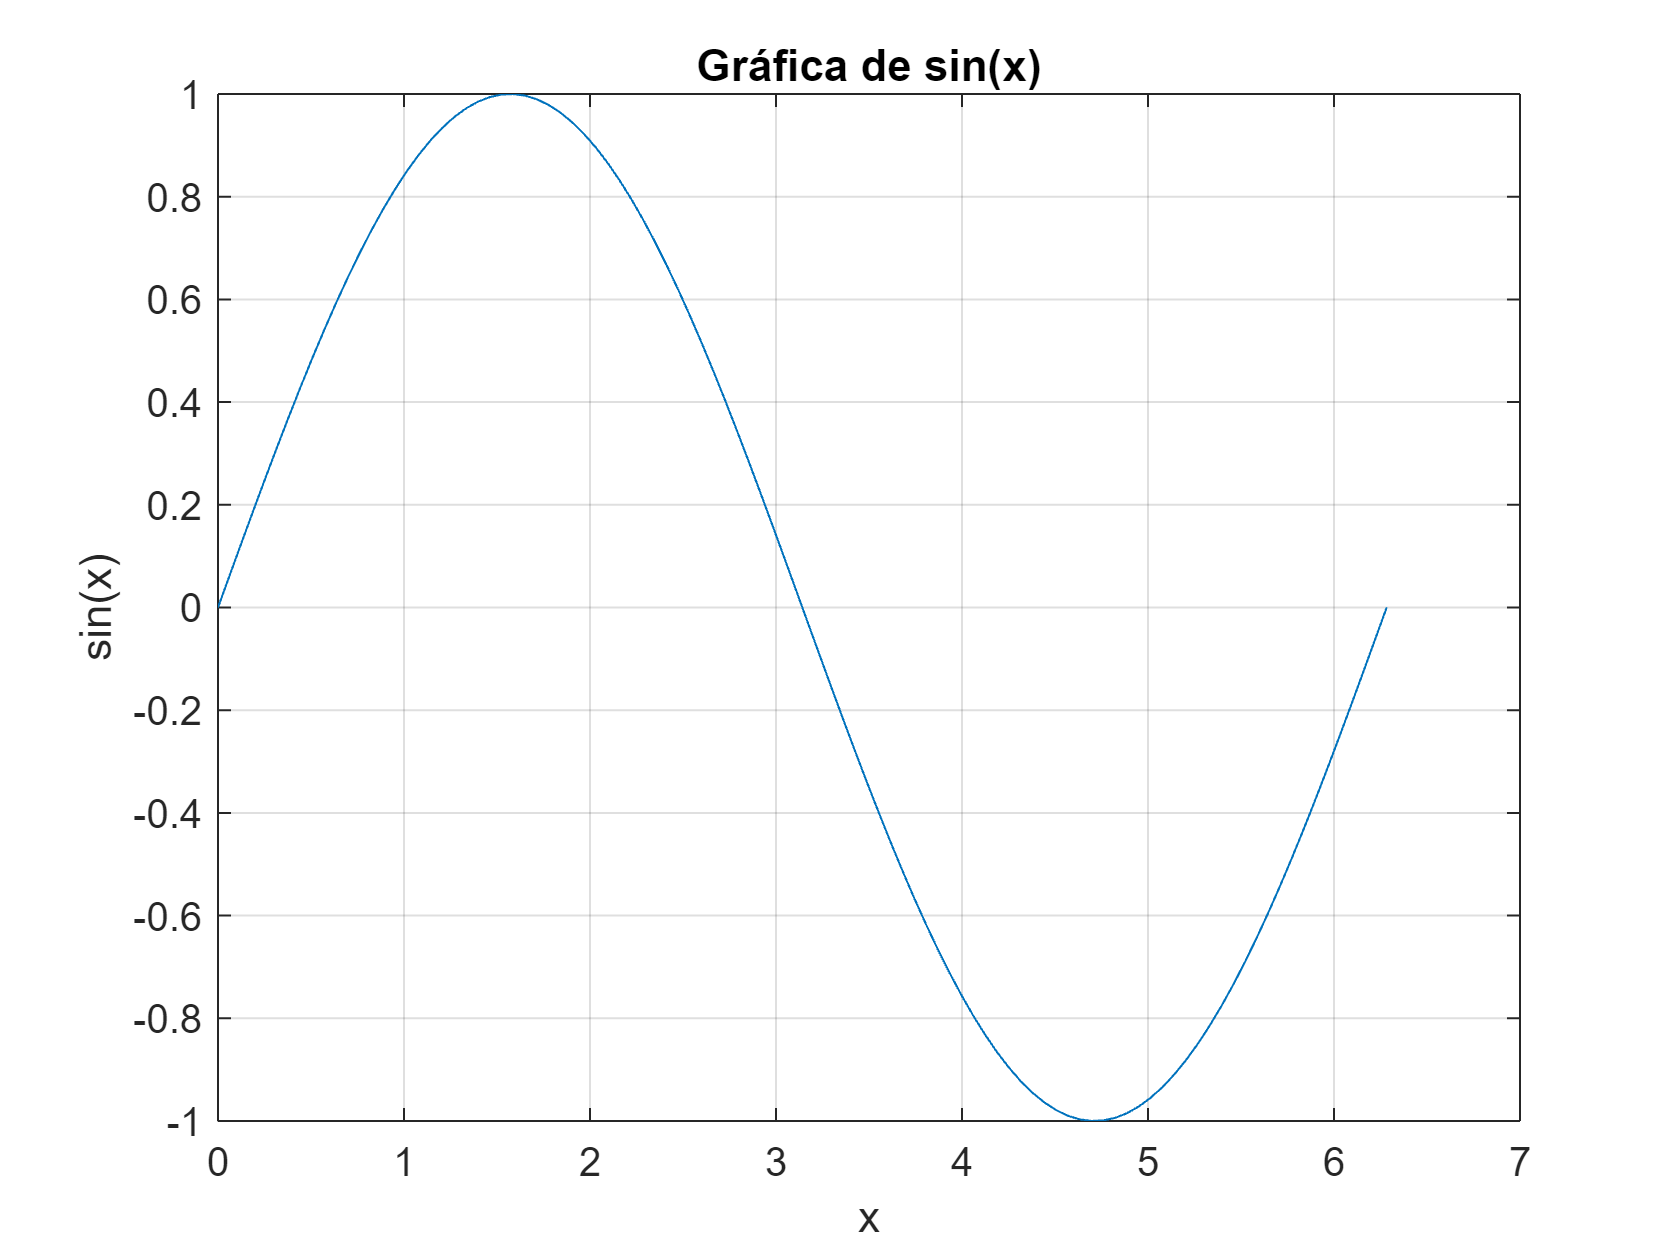

x = linspace(0, 2*pi, 100); % Vector de valores de x
y = sin(x); % Función numérica
plot(x, y) % Graficar
xlabel('x')
ylabel('sin(x)')
title('Gráfica de sin(x)')
grid on

#### **Gráfica polar**

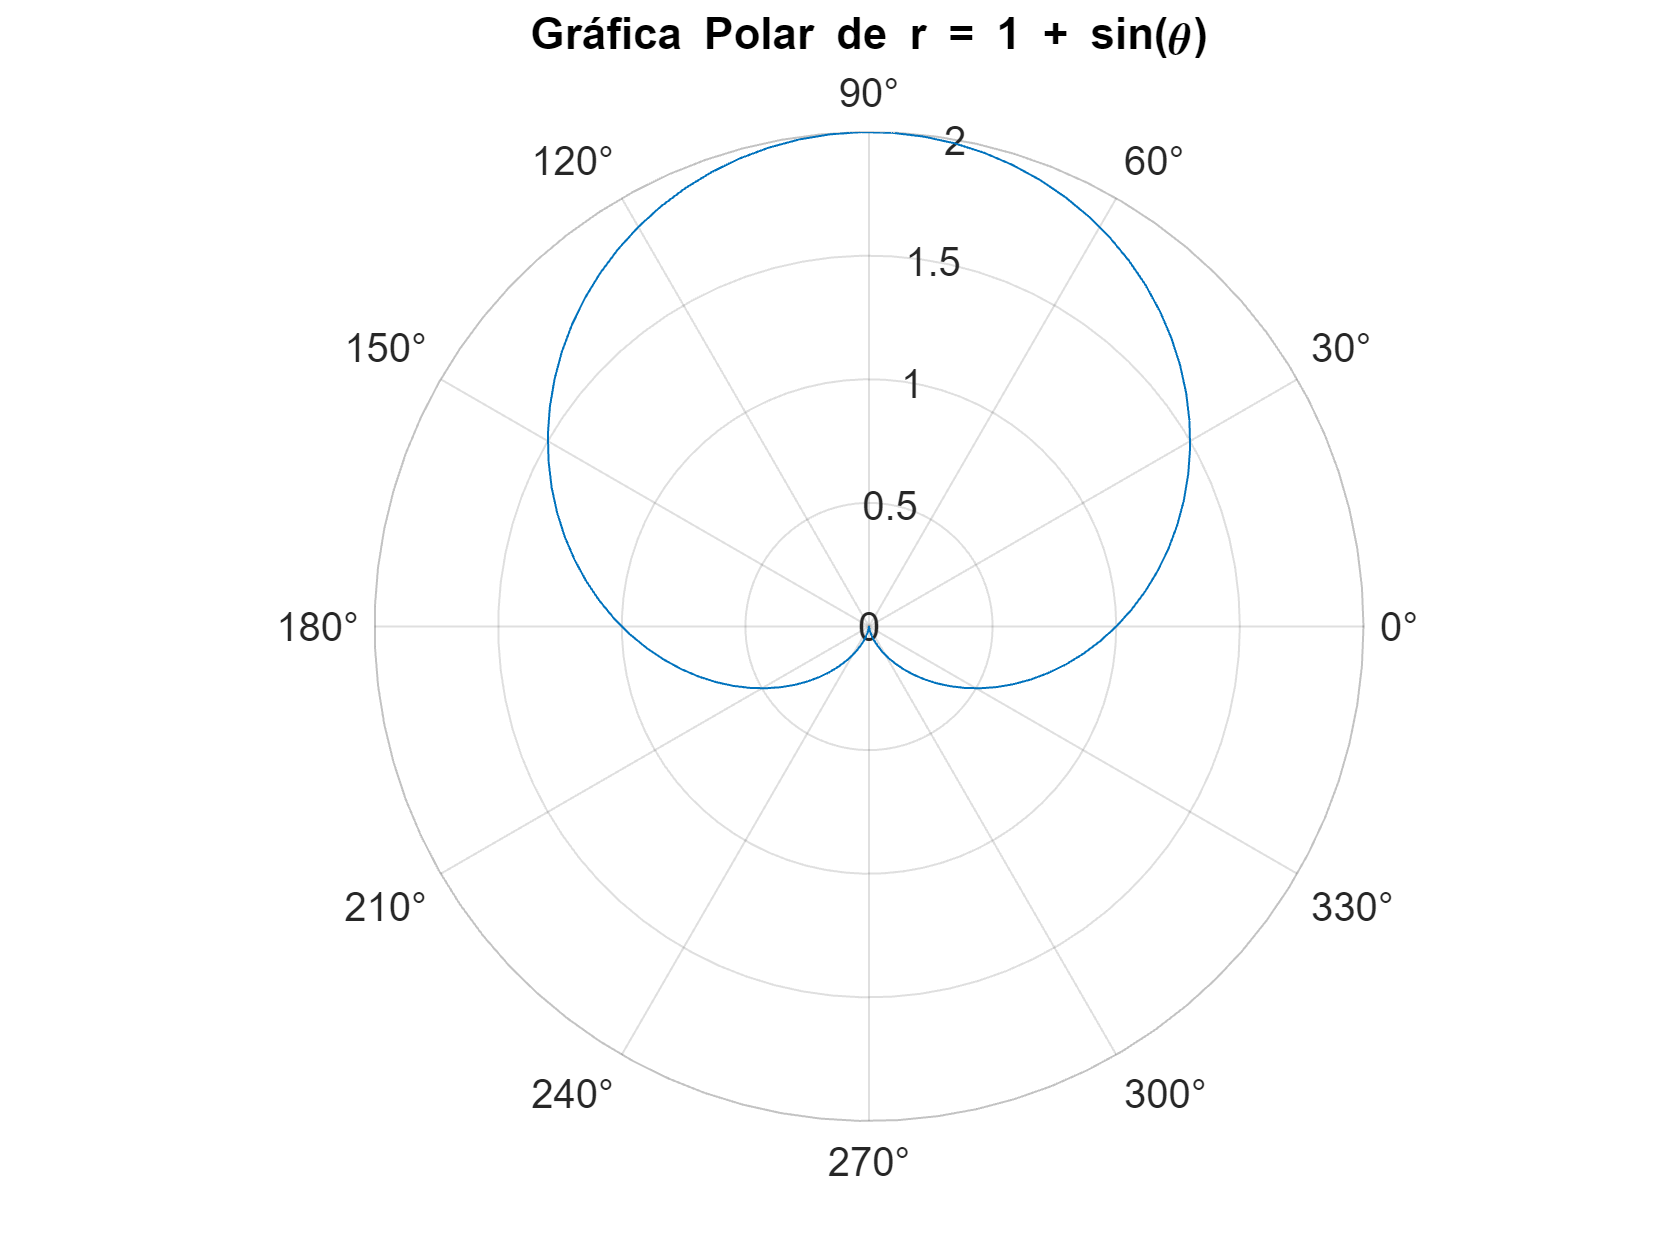

theta = linspace(0, 2*pi, 100); % Ángulo polar
r = 1 + sin(theta); % Función radial
polarplot(theta, r)
title('Gráfica Polar de r = 1 + sin(\theta)')

#### **Gráfica implícita de una ecuación**

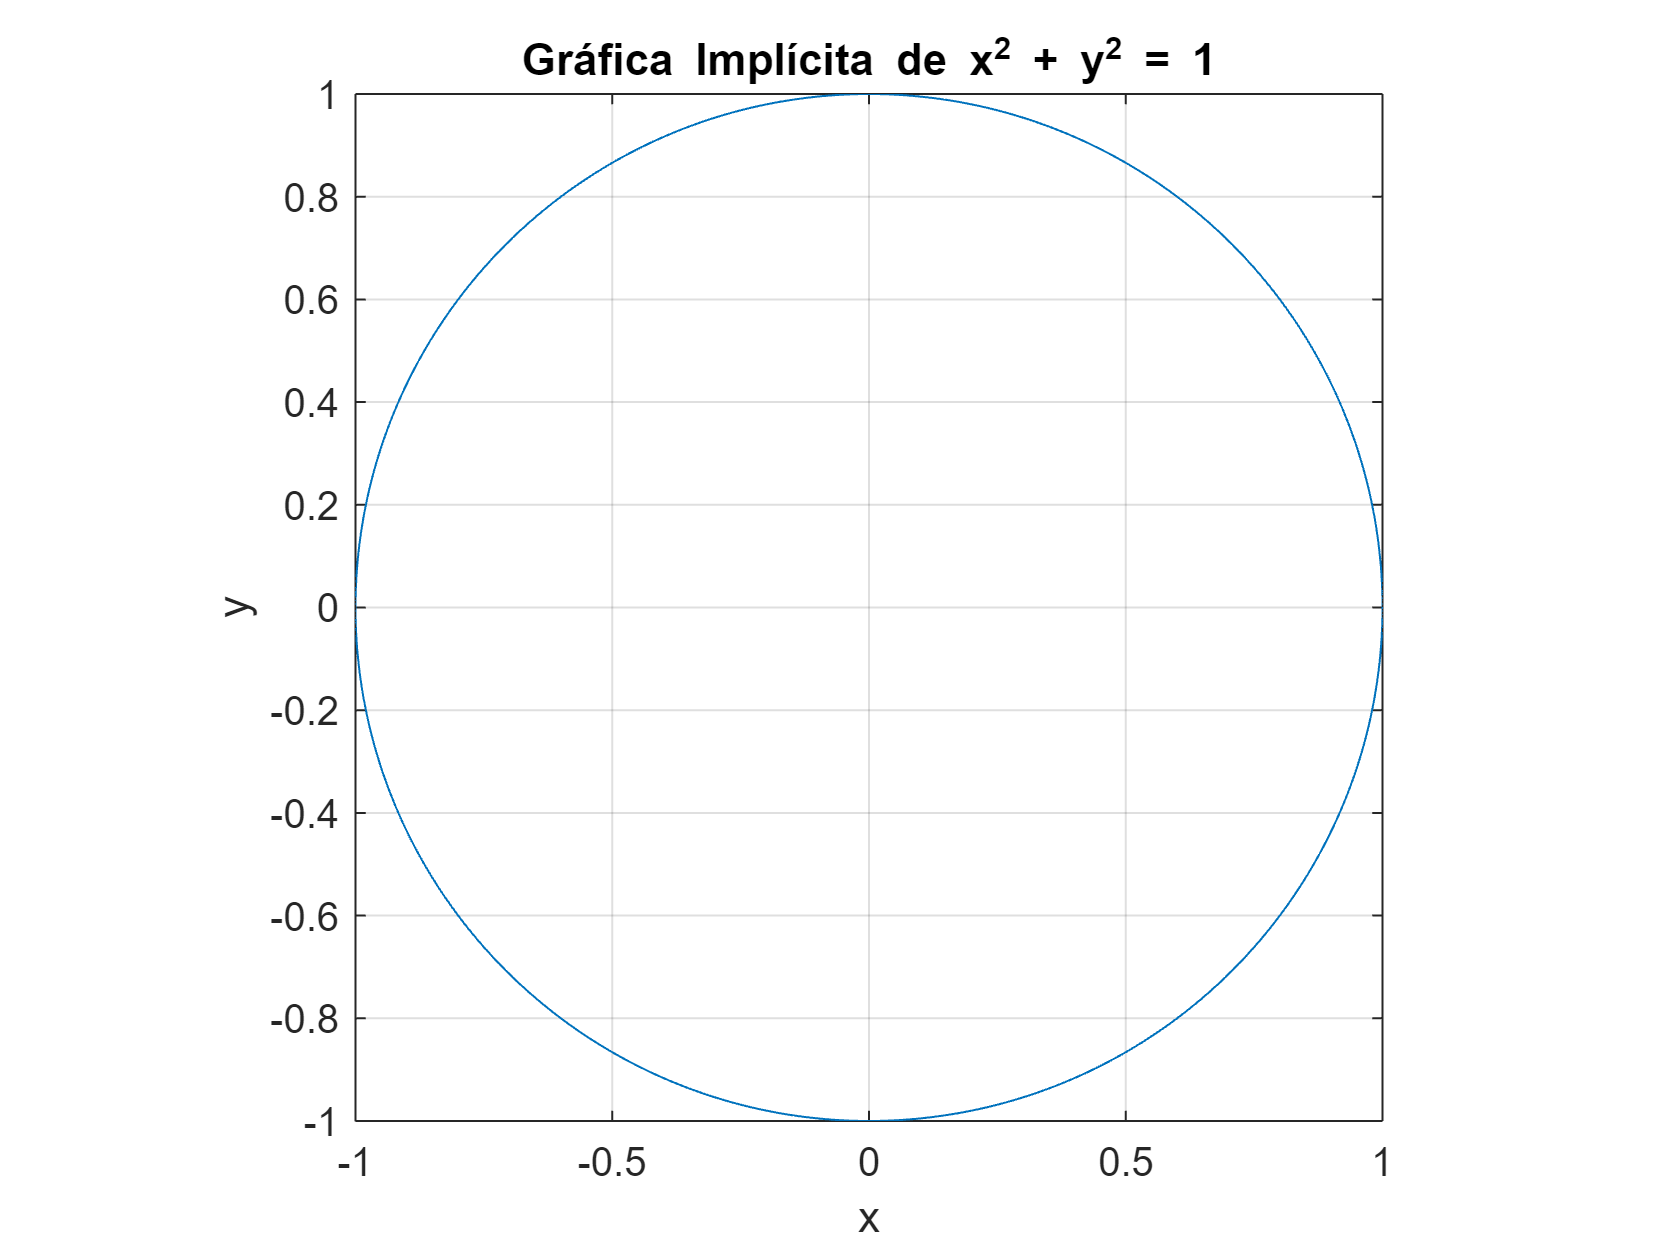

syms x y
fimplicit(x^2 + y^2 - 1) % Ecuación de un círculo: x^2 + y^2 = 1
xlabel('x')
ylabel('y')
title('Gráfica Implícita de x^2 + y^2 = 1')
axis equal
grid on

#### **Gráfica de una función de dos variables**

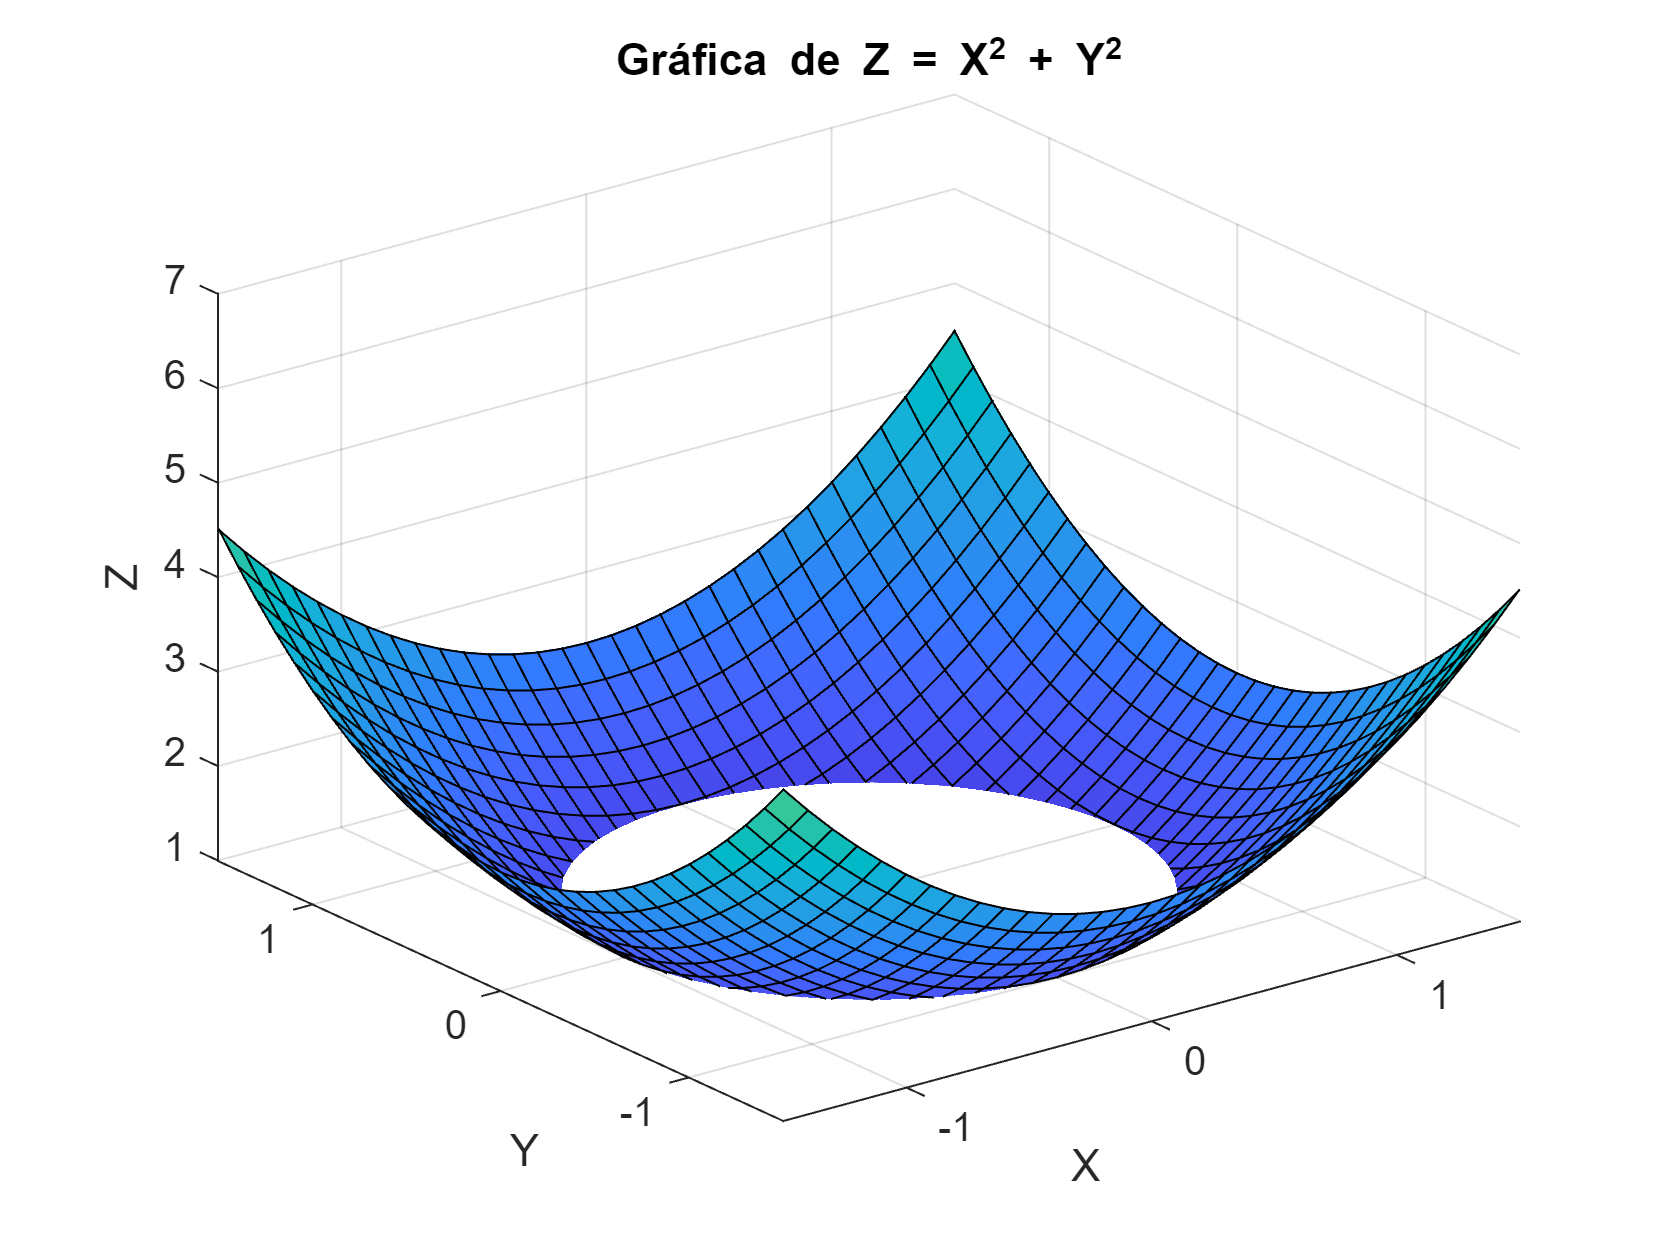

[X, Y] = meshgrid(-2:0.1:2, -2:0.1:2); % Crea una malla de valores
Z = X.^2 + Y.^2; % Función Z = X^2 + Y^2
surf(X, Y, Z) % Gráfica en 3D
xlabel('X')
ylabel('Y')
zlabel('Z')
title('Gráfica de Z = X^2 + Y^2')

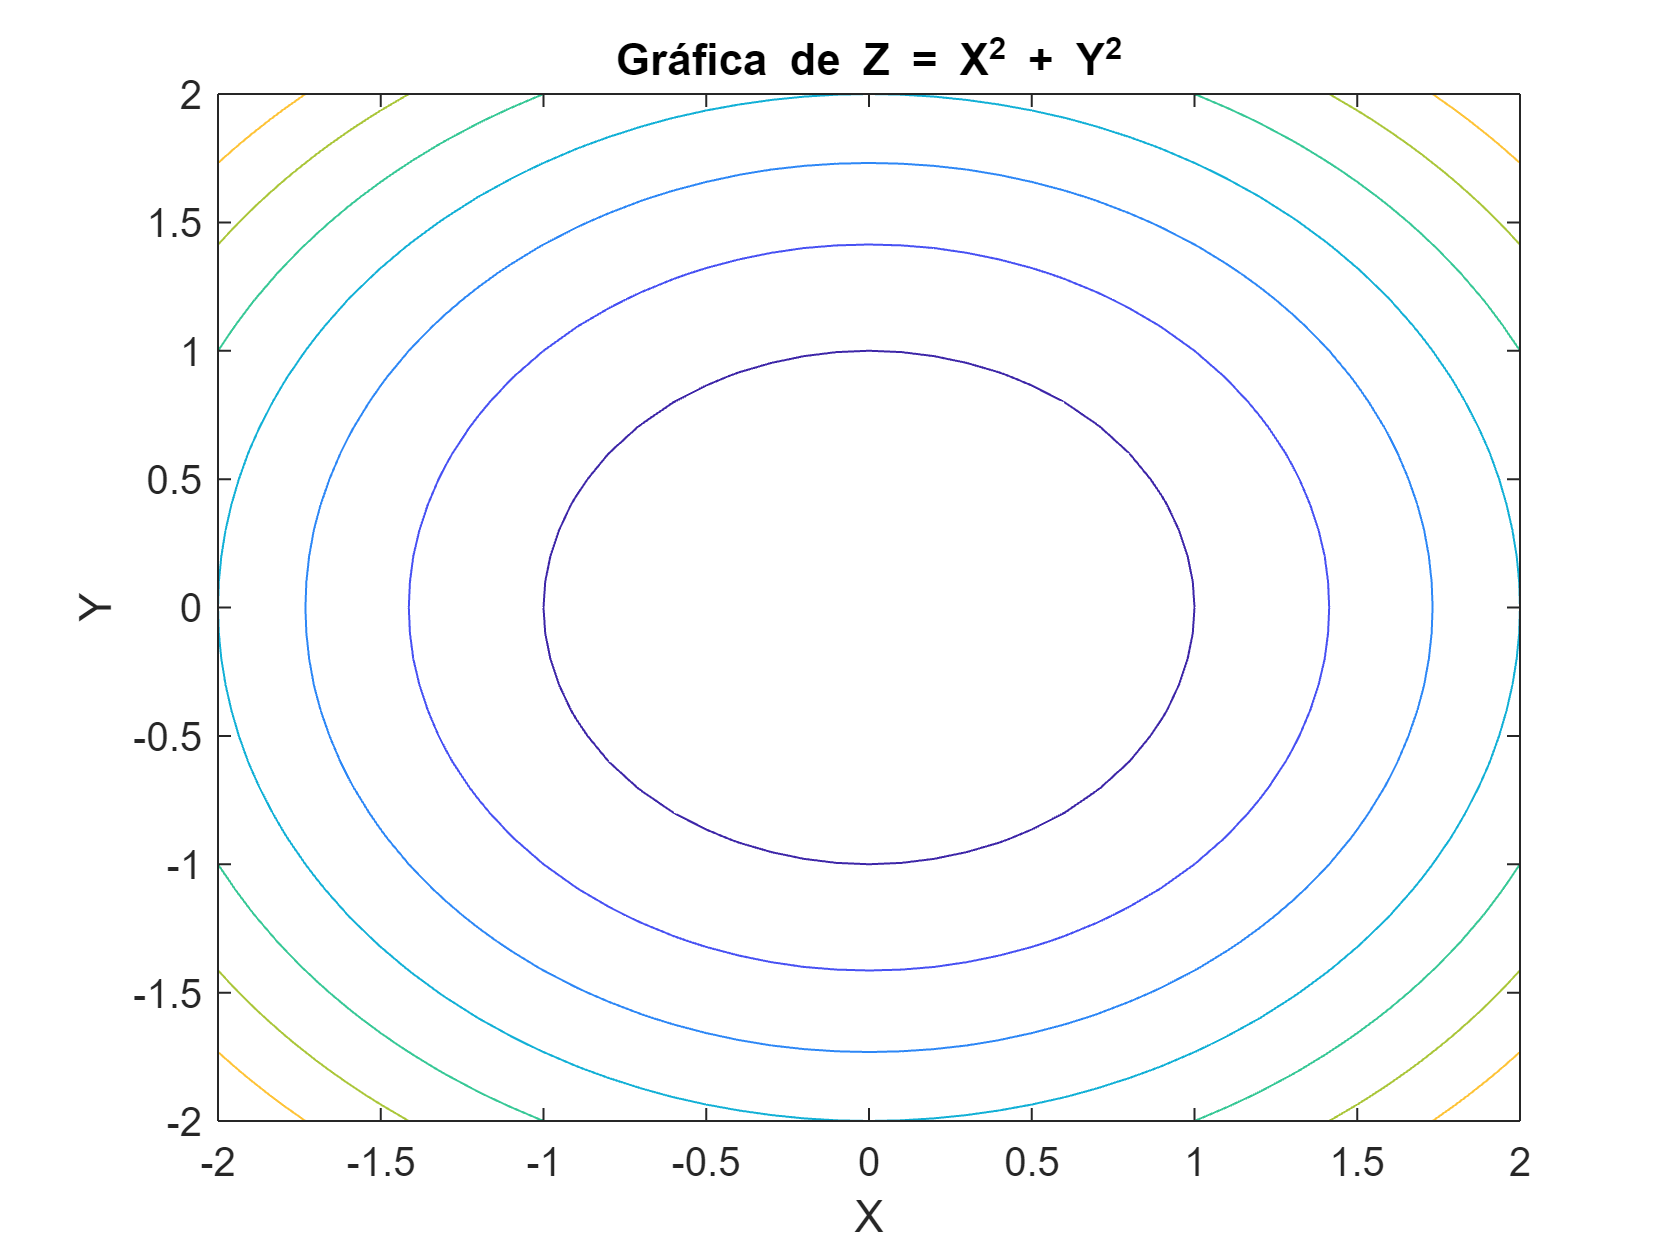

contour(X, Y, Z)
xlabel('X')
ylabel('Y')
title('Gráfica de Z = X^2 + Y^2')

### Archivos de datos

MATLAB ofrece varias funciones para gestionar archivos.

- [`fopen`](https://es.mathworks.com/help/matlab/ref/fopen.html), [`fclose`](https://es.mathworks.com/help/matlab/ref/fclose.html): Apertura y cierre de archivos.

Para ficheros de texto:

- [`fprintf`](https://es.mathworks.com/help/matlab/ref/fprintf.html): Utilizado para escribir texto formateado en archivos de texto.

- [`fscanf`](https://es.mathworks.com/help/matlab/ref/fscanf.html): Permite leer datos de un archivo en un formato específico, similar a `fprintf` pero para la lectura.

- [`textscan`](https://es.mathworks.com/help/matlab/ref/textscan.html): Permite leer de forma versátil archivos de texto con un formato especificado.

Para ficheros binarios:

- [`fwrite`](https://es.mathworks.com/help/matlab/ref/fwrite.html): Similar a `fprintf`, pero se utiliza para escribir datos binarios en un archivo.

- [`fread`](https://es.mathworks.com/help/matlab/ref/fread.html): Se utiliza para leer datos binarios de un archivo.

`Para ficheros de datos generados por Matlab:`

- [`load`](https://es.mathworks.com/help/matlab/ref/load.html): Carga datos de archivos `.mat` o texto en el espacio de trabajo.

- [`save`](https://es.mathworks.com/help/matlab/ref/save.html): Guarda variables del espacio de trabajo en un archivo `.mat`.

**3. ****Funciones de lectura/escritura de formatos específicos**

- [`readtable`](https://es.mathworks.com/help/matlab/ref/readtable.html) y [`writetable`](https://es.mathworks.com/help/matlab/ref/writetable.html): permiten leer y escribir tablas (es decir, variable de tipo table) en archivos CSV o Excel.

- [`jsonencode`](https://es.mathworks.com/help/matlab/ref/jsonencode.html) y [`jsondecode`](https://es.mathworks.com/help/matlab/ref/jsondecode.html): convertir estructuras de MATLAB a JSON y viceversa.

### Argumentos

El bloque [`arguments`](https://es.mathworks.com/help/matlab/ref/arguments.html) permite definir de forma robusta y validar los argumentos de una función.

`arguments`

    `argName1 (dimensions) class {validators} = defaultValue`

`end`

donde:

- `(dimensions)` es una lista de dos o más enteros o : para indicar cualquier dimensión, por ejemplo, `(1,1)` o `(1,:)`.

- `class `es una clase o tipo de dato, como `double`.

- `{validators} `es una lista de funciones de validación, como `mustBeNumeric` o `mustBePositive`. Las funciones `mustBeMember` y `mustBeInRange` permite definir el conjunto o rango de valores del argumento. Puedes consultar la [lista completa](https://es.mathworks.com/help/matlab/matlab_prog/argument-validation-functions.html).

- `defaultValue `es el valor por defecto (puede ser una expresión); al especificarlo, el argumento es opcional y debe ir después de los argumentos no opcionales.

Véase, por ejemplo, la función `f1`:

f1([1 3 5])

ans = 5

f1([1 3 5]') % los vectores fila y columna son compatibles

ans = 5

f1(['1' '3' '5'])

Error using t2>f1
Invalid argument at position 1. Value must be numeric.

### Clases

Una *clase* es una plantilla para crear *objetos*. Define los *atributos* (propiedades) y los *métodos* (funciones) que esos objetos tendrán.

Ejemplo, el objeto `x` de clase `double` puede tener un atributo (como su valor 5,32) y puede ser modificado mediante métodos de la clase, como `exp(x)`.

Ejemplo:

func = @(x) x^2 - 2;
dfunc = @(x) 2*x;
x0_newton = 1;
x0_secante = [1, 1.01];
tol = 1e-6;
maxIter = 100;

metodo = "Newton";

switch metodo
    case "Newton"
        metodo = Newton(x0_newton, tol, maxIter);
    case "Secante"
        metodo = Secante(x0_secante, tol, maxIter);
    otherwise
        error('Método no válido');
end
[raiz, iter] = metodo.ejecutar(func, dfunc);

% Mostrar el resultado
disp("Raíz encontrada: " + raiz + " en " + iter + " iteraciones")

**Ejercicio de clases para la factorización de matrices**

Debes crear una jerarquía de clases para seleccionar y aplicar diferentes tipos de factorizaciones (LU o Cholesky) de una matriz de acuerdo a sus propiedades. Dado un sistema de ecuaciones lineales $Ax = b$, es necesario resolverlo usando una técnica de factorización adecuada. Si la matriz $A$ es simétrica y definida positiva, se utilizará la factorización de Cholesky; si no, se utilizará la factorización LU.

Crea una clase base llamada `Factoriza`, la cual servirá como plantilla para los diferentes tipos de factorizaciones. Esta clase debe tener: 

- Un constructor que reciba la matriz A como parámetro y la almacene.

- Dos métodos abstractos: `factor` y `resol`. El primero debe realizar la factorización de la matriz y el segundo debe resolver el sistema utilizando la factorización obtenida.

Crea dos clases que hereden de `Factoriza`:

- `FactorizaLU`: Implementa la factorización LU.

- `FactorizaChol`: Implementa la factorización de Cholesky.

En el programa principal, se debe determinar el tipo de matriz ingresada. Si es simétrica y definida positiva, se debe utilizar la clase `FactorizaChol`; de lo contrario, se debe utilizar `FactorizaLU` para realizar la factorización y la resolución del sistema.

Requisitos:

- Los métodos numéricos de MATLAB `lu` y `chol` deben ser utilizados para las factorizaciones.

- Se debe usar el operador `\` de MATLAB para resolver los sistemas de ecuaciones.

- Se debe comprobar si la matriz es simétrica y definida positiva utilizando las funciones de MATLAB correspondientes.

Salida esperada:

- El programa debe imprimir el tipo de factorización seleccionada (LU o Cholesky).

- Mostrar la solución del sistema Ax=bAx = bAx=b.

run("../t2_soluciones/solucion3.m")

### Paralelismo

Escoger una [solución para cálculo paralelo](https://es.mathworks.com/help/parallel-computing/choosing-a-parallel-computing-solution.html). En general, se recomienda tener la *Parallel computing toolbox*.

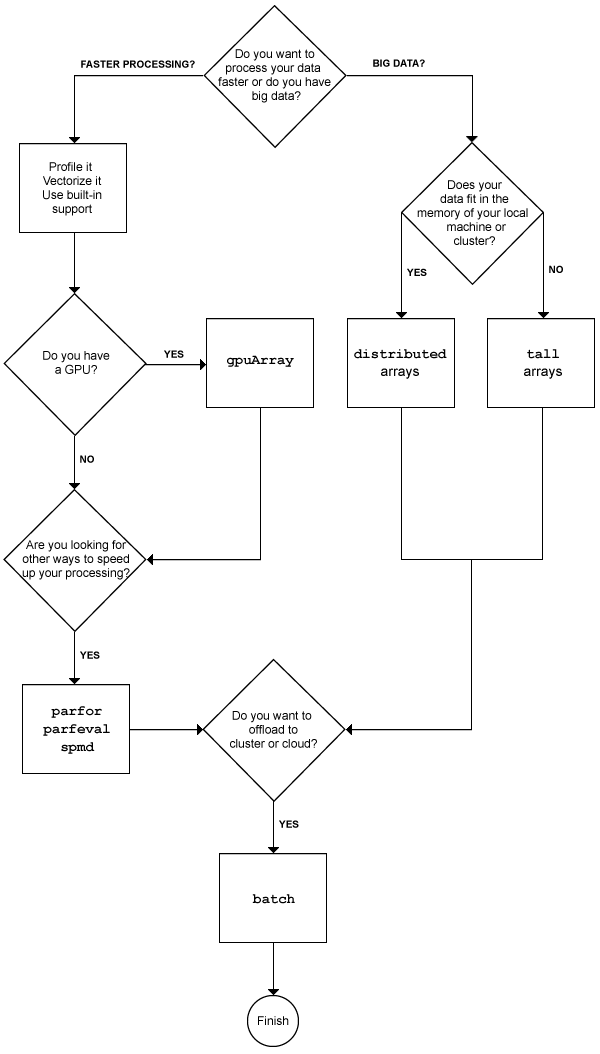

- [**Usar operaciones vectoriales**](https://es.mathworks.com/help/matlab/matlab_prog/vectorization.html): aprovechan varios núcleos del procesador sin hacer nada especial. 

- [`parfor`](https://es.mathworks.com/help/matlab/ref/parfor.html): bucles paralelizados.

- [**Clusters**](https://es.mathworks.com/help/parallel-computing/quick-start-parallel-computing-in-matlab.html):  paradigma *master - worker*

- [***GPU***](https://es.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html)

#### Medida de tiempos

Se recomienda[ medir el rendimiento del código](https://es.mathworks.com/help/matlab/matlab_prog/measure-performance-of-your-program.html).

- [`tic, toc`](https://es.mathworks.com/help/matlab/ref/tic.html?searchHighlight=tic)`:` inicio y parada de una medición.

- [`timeit`](https://es.mathworks.com/help/matlab/ref/timeit.html): medición de una función.

- [**Perfilado**](https://es.mathworks.com/help/matlab/matlab_prog/profiling-for-improving-performance.html): medir el tiempo de ejecución e identificar cuellos de botella, con [`profile`](https://es.mathworks.com/help/matlab/ref/profile.html).

- [`checkcode`](https://es.mathworks.com/help/matlab/ref/checkcode.html): chequea el código en busca de posibles problemas.

## **Anexo. Funciones locales**

En Matlab, las funciones locales utilizadas en un *script*, van al final de éste.

function m = f1(x)
    arguments
        x (1,:) {mustBeNumeric}
    end
    m = max(x);
end